# Simulink環境での学習

## 環境のインスタンス

### 環境のパラメータ

clear all
close all
Ts = 0.01;
Tf = 30;

### Simulink モデルのロード及びパラメータ設定

mdl = "rlMobileRobotMdl";
load_system(mdl);

### 強化学習環境のインスタンス

agentBlk = mdl + "/RL Agent";
observationInfo = rlNumericSpec([4 1]);
actionInfo = rlNumericSpec([2 1]);

env = rlSimulinkEnv(mdl, agentBlk, observationInfo, actionInfo);
rng(0);

## エージェントの作成

### エージェントオプションの作成

moduleAgentOpts = rlLQTAgentOptions('StepNumPerIteration', 20, ...
                                    'DiscountFactor', 0.99, ...
                                    'StopExplorationValue', 0, ...
                                    'SaveExperiences', true);
agentOpts = rlAdaptiveModularAgentOptions("SampleTime", Ts, ...
                                          "Vigilance", -Inf, ...
                                          "SaveExperiences", true);

### ノイズモデルの生成

moduleAgentOpts.NoiseOptions.Mean = 0;
moduleAgentOpts.NoiseOptions.Variance = 2;

### エージェントのインスタンス

createModuleFcn = @(x, y) createLQTAgentModule(getObservationInfo(env), getActionInfo(env), moduleAgentOpts, x, y);
agent = rlAdaptiveModularAgent(createModuleFcn, agentOpts);

## エージェントの学習

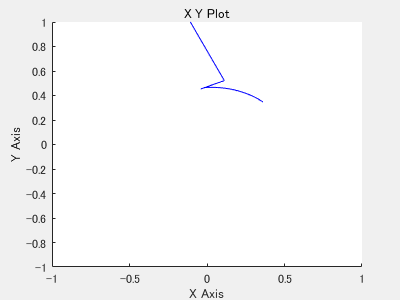

Episode:   1/  1 | Episode Reward : -Inf | Episode Steps:  460 | Avg Reward : -Inf | Step Count : 460


エラー: rl.env.AbstractEnv/simWithPolicy (line 70)
An error occurred while simulating "rlMobileRobotMdl" with the agent "agent".

エラー: rl.task.SeriesTrainTask/runImpl (line 33)
            [varargout{1},varargout{2}] = simWithPolicy(this.Env,this.Agent,simOpts);

エラー: 

trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',1, ...
    'MaxStepsPerEpisode',Tf / Ts, ...
    'StopTrainingValue', 100000, ...
    'Verbose',true, ...
    'Plots','none');

trainingStats = train(agent, env, trainingOpts);

## 実験結果のプロット

experience = getExperiences(agent);

observation     = cellfun(@(x)x{1},experience,'UniformOutput',false);
action          = cellfun(@(x)x{2},experience,'UniformOutput',false);
reward          = cellfun(@(x)x{3},experience,'UniformOutput',false);
nextobservation = cellfun(@(x)x{4},experience,'UniformOutput',false);
isdone          = cellfun(@(x)x{5},experience,'UniformOutput',false);
selectedModuleID = getBuffer(agent.SelectedModuleID);
evaluateValues = getBuffer(agent.EvaluateValues);
t = 0 : Ts : Tf - Ts;

### 行動のプロット

action = cell2mat(transpose(cellfun(@(x) x{:}, action, 'UniformOutput', false)));
figure
plot(t, action);

### 状態遷移のプロット

observation = cell2mat(transpose(cellfun(@(x) x{:}, observation, 'UniformOutput', false)));
figure
plot(t, observation(1, :), t, observation(2, :));

### 報酬のプロット

figure
plot(cell2mat(reward));

## 選択されたモジュールのプロット

figure
plot(cell2mat(selectedModuleID))

### 各モジュールの評価値をプロット

for i = 1 : length(agent.ModuleAgents)
    module{i} =  cellfun(@(x) extractEvaluateValues(x, i), evaluateValues);
    subplot(length(agent.ModuleAgents), 1, i);
    plot(t, module{i})
    xlim([min(t) max(t)])
end

function ret = extractEvaluateValues(val, moduleID)
    if length(val) < moduleID
        ret = nan;
    else
        ret = val(moduleID);
    end
end